# **EllipticC**

[Complete elliptic integral C](http://apps.nrbook.com/bateman/Vol2.pdf)

## Definition


$$C\left(m\right)\equiv \int_0^{\pi /2} \frac{\sin^2 \theta \;\cos^2 \theta \;d\theta \;}{\sqrt{1-m\;\sin^2 \theta }}=\int_0^1 \frac{t^2 \left(1-t^2 \right)\;\mathit{dt}}{\sqrt{\left(1-t^2 \right)\left(1-m\;t^2 \right)}}$$



$$\mathit{\mathbf{C}}\left(k\right)\equiv C\left(k^2 \right)$$


where *k *is the modulus, *m *is the parameter ([3] pp 321).

Domain: $1-m\ge 0$, $|k|\le 1$. For the specified domain, the  codomain is the set of real numbers.

Special values:

$C\left(-\infty \right)=0,$   $C\left(0\right)=\frac{\pi }{16}$,   $C\left(1\right)=\infty$

Identities:


$$C\left(m\right)=\frac{\left(2-m\right)\;K\left(m\right)-2E\left(m\right)}{m^2 }$$


where *K *and *E *are complete elliptic integrals of the first and the second kind ([4] pp 73), .

## Syntax

Y = EllipticC(K)

y = elC(k)

Y = mEllipticC(M)

y = melC(m)

## Description

**Y = EllipticC(K)** returns the value of the complete elliptic integral  $\mathit{\mathbf{C}}\left(k\right)$ for each element of the array  K (modulus).  K must be real array or scalar. **EllipticC** is the wrapper function which calls the functions **melC** element-wise via the function **ufun1**.

**y = elC(k)** returns the value of the complete elliptic integral  $\mathit{\mathbf{C}}\left(k\right)$ for  the modulus k. It is assumed that  k is real scalars without check. y is NaN if k is invalid or convergence failed. **elC** is the wrapper function which calls the functions **melC**.

**Y = mEllipticC(M)** returns the value of  the complete elliptic integral $C\left(m\right)$ for each element of the array  M (parameter).  M must be real array or scalar. **mEllipticC** is the wrapper function which calls the functions **melC** element-wise via the function **ufun1**.

**y = melC(m)** compute value of  the complete elliptic integral  $C\left(m\right)$ for  the parameter m. It is assumed that  m is real scalars without check. y is NaN if m is invalid or convergence failed.  **melC **call the Carlson's function **rf **for calculation of $C\left(m\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5; % |k|<= 1
[elC(k), EllipticC(k), melC(k^2), mEllipticC(k^2)]

ans =    0.242219235891020   0.242219235891020   0.242219235891020   0.242219235891020


m = 0.5; % |m|<1 
[elC(sqrt(m)), EllipticC(sqrt(m)), melC(m), mEllipticC(m)]

ans =    0.319297015426827   0.319297015426827   0.319297015426827   0.319297015426827


Accuracy. 

fprintf('%.16g\n',melC(-4))  % Maple 18D 0.04914689354650059 25

0.04914689354650068


melC(0.02) % =0.19934 (Jahnke, Emde, 1945, pp 82)

ans = 0.1993

melC(0.52)  % =0.3279 (Jahnke, Emde, 1945, pp 82)

ans = 0.3279

melC(0.94) % % =0.9620 (Jahnke, Emde, 1945, pp 82)

ans = 0.9620

Special values

melC(-inf)

ans = 0

disp(melC(0) - pi/16)

     0



melC(1)

ans = Inf

melC(10)  % if m > 1 then C(m) = NaN

ans = NaN

Identities

m=-0.2;
disp(mEllipticC(m) - ((2-m)*mEllipticK(m)-2*mEllipticE(m))/m^2)

    -1.551536676913656e-14



**Vector input**

Identities

k = [-0.2, -0.1, 0.5, 0.9];
disp(EllipticC(k) - ((2-k.^2).*EllipticK(k)-2*EllipticE(k))./k.^4)

   1.0e-12 *

   0.105471187339390   0.910382880192628  -0.000888178419700   0.001332267629550



**Matrix input**

Identities

M=[-1/2 1/3 1/4; 1/2 -1/3 -1/4];
disp(mEllipticC(M) - ((2-M).*mEllipticK(M)-2*mEllipticE(M))./M.^2)

   1.0e-14 *

   0.088817841970013   0.466293670342566  -0.088817841970013
   0.044408920985006  -0.133226762955019   0.266453525910038



## **Plot**

**Example 1**

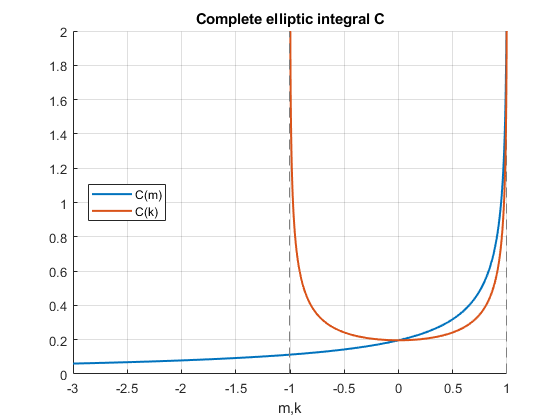

figure
hold on
fplot(@(m) mEllipticC(m),[-3,1],'LineWidth',1.5)
fplot(@(k) EllipticC(k),[-3,1],'LineWidth',1.5)
title('Complete elliptic integral C')
ylim([0 2])
legend('C(m)','C(k)','Location','best')
xlabel('m,k')
grid on
hold off

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

[3] A. Erd´elyi et al., Higher Transcendental Functions Vol. II, California Institute of

Technology - Bateman Manuscript Project, 1953-1955 McGraw-Hill Inc. 

[4] E.Jahnke, F. Emde, Tables of Functions, 4th ed, Dover,  1945

## See Also